# `Fall 2024 BENG 135 Biomedical Signals & Systems`

## `Problem Set 1`

`Written by F Contijoch. Thanks to K Lamar Bruno (TA FA23)`

### `Problem 0 Design Plot Code`

Your first task is to write a function called myPlot (declared in [myPlot.m](matlab:open('./myPlot.m'))). A full description of the function can be found in [myPlot.m](matlab:open('./myPlot.m'))**.**

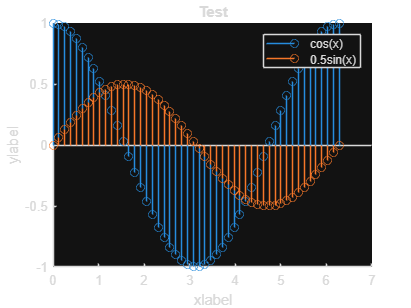

testTitle = "Test";
xlabel ="xlabel";
ylabel ="ylabel";
labels =["cos(x)", "0.5sin(x)"];
X = linspace(0,2*pi,50);
Ys = [cos(X); 0.5*sin(X)];
myPlot(X, Ys, testTitle, xlabel, ylabel, labels, "stem");

### `Problem 1 Analyzing Signals`

In this section, we will focus on how to quantify the amount of noise in a signal and introduce some methods to remove noise. 

Suppose we are measuring the following sinusoid, but our measurement comes with added gaussian noise: 

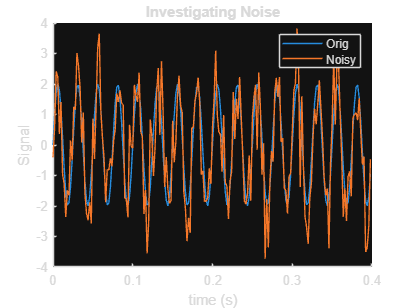

fs = 500; %% Sampling Rate (Hz)
N = 200;
t = (0:N-1)/fs;
f = 40; %% Frequency (Hz)
stdev = 1;
signal = 2*sin(2*pi*f*t);
noisySignal = signal + stdev*randn(N,1)';
myPlot(t, [signal; noisySignal], "Investigating Noise", "time (s)", "Signal", ["Orig","Noisy"], "continuous");

`[Problem 1.1] `Write a function getSNR that calculates the Signal-to-Noise Ratio (SNR) in decibels (dB). Full description can be found in [getSNR.m](matlab:open('./getSNR.m')). 

SNR = getSNR(signal',noisySignal') %Replace with your code. getSNR should be used

NoisePower = 2.8156

snr = -1.4853

SNR = -1.4853

`[Problem 1.2] ``Use `[`histfit`](https://www.mathworks.com/help/stats/histfit.html#btg7b6c-1)` to plot the histogram of the noise of the data. `

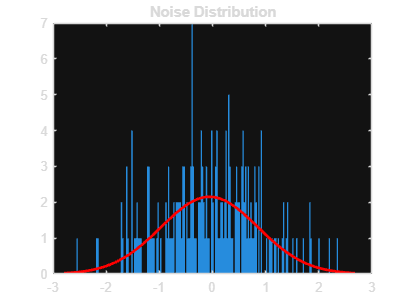

% Your code here 
noise = noisySignal - signal;

figure
histfit(noise, size(signal,2), 'normal')
title("Noise Distribution")

`[Problem 1.3] ``Use `[`fitdist`](https://www.mathworks.com/help/stats/fitdist.html)` to find the mean and standard deviation of the fitted normal distribution. `

`Write the mean and standard deviation of your fitted pdf below:`

`Mean = -0.0354`

`Standard Deviation = 1.0244`

%Your code here
pd = fitdist(noise', 'Normal');

meanNoise = pd.mean;
stdNoise = pd.std;

fprintf('Mean of the fitted normal distribution: %.4f\n', meanNoise);

Mean of the fitted normal distribution: -0.0565


fprintf('Standard deviation of the fitted normal distribution: %.4f\n', stdNoise);

Standard deviation of the fitted normal distribution: 0.9115


`[Problem 1.4] ``We want an SNR of at least 20 dB. We will use averaging to help reduce the noise. `

`[Theoretically]`` How many averages will we need to get the SNR to be at least 20 dB? Explain. Your answer should be a function of the variable SNR declared in ``Problem 1.1``. `

`If your new SNR is lower than 20 dB,  explain why:`

numAvgs = 0; %Replace with your code (should be dependent on variable SNR)

targetSNR = 20;

numAvgs = ceil(10^((targetSNR - SNR)/10));
numAvgs = max(1, int16(numAvgs));

fprintf('Number of averages required to reach an SNR of at least 20 dB: %d\n', numAvgs);

Number of averages required to reach an SNR of at least 20 dB: 141


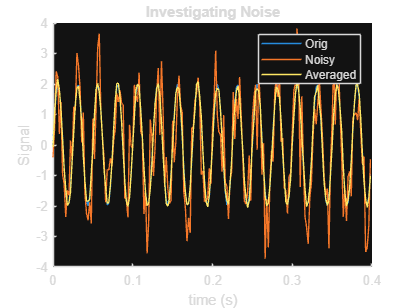


noisySignals = [];
for m = 1:numAvgs
    noisySignals = [noisySignals; signal + stdev*randn(N,1)'];
end
noisySignals = [noisySignals; noisySignal];
processed = mean(noisySignals, 1);
myPlot(t, [signal; noisySignal; processed], "Investigating Noise", "time (s)", "Signal", ["Orig","Noisy", "Averaged"], "continuous");

processedSNR = getSNR(signal',processed') %Replace with your code

NoisePower = 2.0194

snr = -0.0420

processedSNR = -0.0420

### `Problem 2 Convolution`

In the time domain, LTI systems act by convolving an input with the system's impulse response. LTI systems are therefore completely characterized by their impulse responses! 

We will start with a convolution walkthrough. The best place to start is with the definition. 

$y [n]= x \ast h [n] = \sum_{k = -\infty}^{\infty} x[k]h[n-k]$  `(Discrete)`

$y(t) = x\ast h(t) = \int_{-\infty}^{\infty}x(u)h(t-u) du$ ` (Continuous)`

We will break down the discrete definition in order to build intuition. Notice that we can rewrite the definition as follows. 

Let $n\in \mathbb{Z}$, set $g\left\lbrack k\right\rbrack =h\left\lbrack n-k\right\rbrack$


$$y [n]= x \ast h [n] = \sum_{k = -\infty}^{\infty} x[k]g[k] = x \cdot g $$
 

Each time point $n$ of the convolution of the signals $x\;$and $h$ is merely a dot product of $x\;$and a shifted $h$. 

**We will now construct the convolution of the following two signals:**

$x\;\left\lbrack n\right\rbrack =\delta \left\lbrack n+1\right\rbrack +2$$\delta \left\lbrack n\right\rbrack$ + $3\delta \left\lbrack n-1\right\rbrack$


$$h\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack +\delta \left\lbrack n-1\right\rbrack$$


**Recall: The Delta Function **

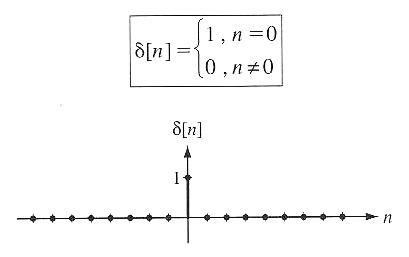

% Signals (first index is i = 1 which corresponds to t = -1)
X = [1 2 3]; %% length = 3
H = [0,1,1]; %% length = 2
Y= zeros(1, 3 + 2 - 1);

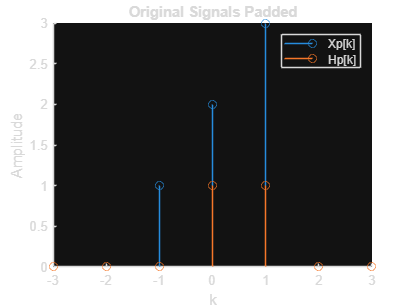

k = [-3 -2 -1 0 1 2 3];
X_pad = [0 0 1 2 3 0 0];
H_pad = [0 0 0 1 1 0 0];

myPlot(k, [X_pad; H_pad], "Original Signals Padded", "k", "Amplitude", ["Xp[k]", "Hp[k]"], "stem")

`[Problem 2.1]`` We will break convolution down into shifted dot products. You will need to set H_shifted appropriately such that y[n] = dot(X,H_shifted) for the requested n value. `

Find $y\left\lbrack 0\right\rbrack$

H_shifted = [0, 0, 0, 1, 1, 0, 0];

y0 = dot(X_pad, H_shifted) %Replace with your code

y0 = 5

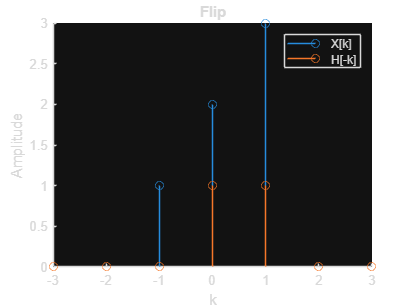

%Uncomment the following lines after you set Hshift
myPlot(k, [X_pad; H_shifted], "Flip", "k", "Amplitude", ["X[k]", "H[-k]"], "stem");

Y(2) = dot(X_pad, H_shifted,2);

Find $y\left\lbrack -1\right\rbrack$ 

H_shifted = [0, 0, 1, 1, 0, 0, 0];

yneg1 = dot(X_pad,H_shifted) %Replace with your code

yneg1 = 3

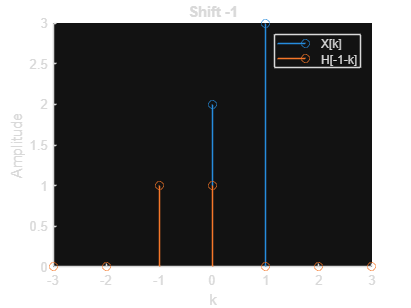

%Uncomment the following lines after you set Hshift
myPlot(k, [X_pad; H_shifted], "Shift -1", "k", "Amplitude", ["X[k]", "H[-1-k]"], "stem");

Y(1) = dot(X_pad, H_shifted,2);

Find $y\left\lbrack 1\right\rbrack$ 

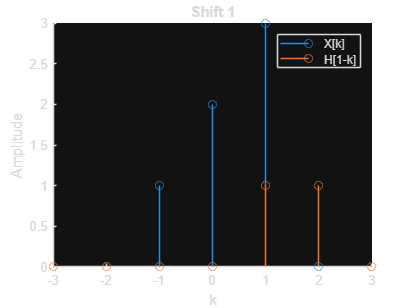

H_shifted = [0, 0, 0, 0, 1, 1, 0];

y1 = dot(X_pad, H_shifted); %Replace with your code
%Uncomment the following lines after you set Hshift
myPlot(k, [X_pad; H_shifted], "Shift 1", "k", "Amplitude", ["X[k]", "H[1-k]"], "stem");

Y(3) = dot(X_pad, H_shifted,2);

Find $y\left\lbrack 2\right\rbrack$

H_shifted = [0, 0, 0, 0, 0, 1, 1];
y2 = dot(X_pad, H_shifted) %Replace with your code

y2 = 0

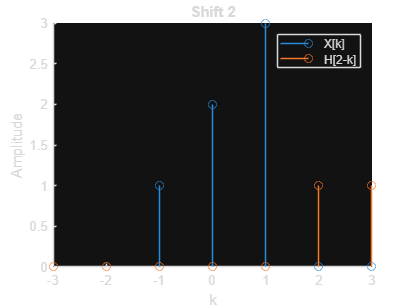

%Uncomment the following lines after you set Hshift
myPlot(k, [X_pad; H_shifted], "Shift 2", "k", "Amplitude", ["X[k]", "H[2-k]"], "stem");

Y(4) = dot(X_pad, H_shifted,2);

`[Problem 2.2] ``Find `$y\left\lbrack n\right\rbrack$` for all `$n\in \mathbb{N}$ `such that `$n>2$`. Your answer should be a real value. Justify your answer.`


$$y\left\lbrack n\right\rbrack =0$$
 

**Justification: As H_shifted moves to the right, the non-zero portion of H_shifted overlaps over the empty or zero portion of X_Pad. Because of this the dot product is always zero.**

`[Problem 2.3] ``Find `$y\left\lbrack n\right\rbrack$` for all `$n\in \mathbb{N}$ `such that `$-1>n$`. Your answer should be a real value. Justify your answer.`


$$y\left\lbrack n\right\rbrack =0$$
 

**Justification: Similarly to above, shifting the H_shifted value to the left also results in the nonzero portions of H_shifted overlapping with the zeros of X_pad and therefore resulting in y[n] = 0.**

Verify that your constructed convolution is equivalent to Matlab's [conv](https://www.mathworks.com/help/fixedpoint/ref/conv.html).

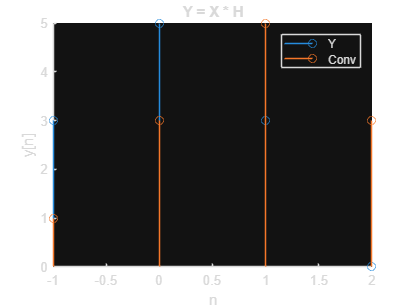

matlabConv = conv(X,fliplr(H));
matlabConv = matlabConv(1:length(matlabConv)-1);
myPlot( [-1 0 1 2], [Y; matlabConv], "Y = X * H", "n", "y[n]", ["Y", "Conv"], "stem");

### `Problem 3 Cross Correlation`

The normalized cross-correlation of two deterministic discrete signals $x$ and $h$, is defined as the following. Notice that the normalized cross-correlation of $x$ and $h$ is a scaled and shifted convolution of $u$ and $h$.


$$R_{xh}[n] = \; \; \frac{\sum_{k=-\infty}^{\infty} x[k]h[n + k]}{\left(\sqrt{\sum_{k=-\infty}^{\infty} |x[k]|^2}\right) \left(\sqrt{\sum_{k=-\infty}^{\infty} |h[k]|^2}\right)} \; \; $$


`[Problem 3.1] ``Write a function crossCorr (`[`crossCorr.m`](matlab:open('./crossCorr.m'))`) that will return the cross correlation of two signals. Verify below that your function outputs the same signal that Matlab's `[`xcorr`](https://www.mathworks.com/help/matlab/ref/xcorr.html)` finds.`

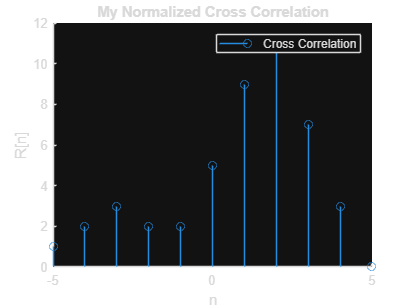

X = [1, 2, 3, 2, 1, 0];
H = [3, 1, 0, 0, 0, 1];

[cross, lags] = crossCorr(X, H);
[matCross, matLags] = xcorr(X, H, "Normalized");

myPlot(lags, [cross], "My Normalized Cross Correlation", "n", "R[n]", ["Cross Correlation"], "stem");

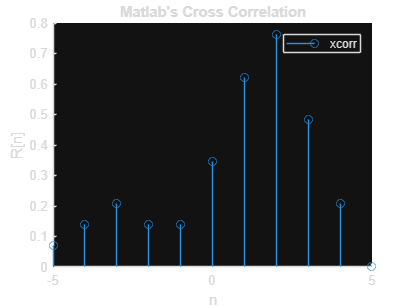

myPlot(matLags, [matCross], "Matlab's Cross Correlation", "n", "R[n]", ["xcorr"], "stem");

### `Problem 4 Applications of Cross Correlation`

You are provided with a respiratory signal in [resp.mat](matlab:open('./resp.mat')). 

`[Problem 4.1]`` Write a function `[`autocorr.m`](matlab:open('./autocorr.m'))` that outputs the autocorrelation and lags of an input signal. `

`Use this function to calculate the autocorrelation of the respiratory data. `

`Estimate the period (T) of the respiratory signal from the plot of the autocorrelation. `

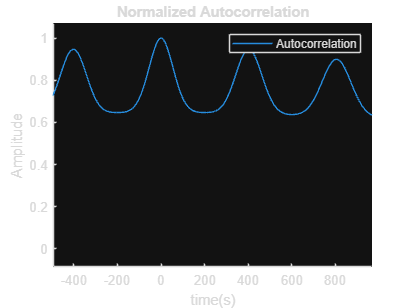

data = load("resp.mat");
[acorr,lags] = autocorr(data.resp);
t = lags; %Replace with your code
myPlot(t, [acorr], "Normalized Autocorrelation", "time(s)", "Amplitude", ["Autocorrelation"], "continuous");
axis([-20 20 -0.2 1.2]);

xlim([-500 500])
ylim([-0.20 1.20])

T  = 400; %Replace with your estimation

